# Cosmology Calculations

Lauri Jokinen, 2020.

This document is used together with file `runge_kutta.m` for plotting figures. The script is made with Matlab version 2020a, with Live Script enabled. The code is much more readable with Live Script swiched on.

The script has a function for each plot, and the functions are called in section 'Calling the plotting Functions'. This way toggling the plots on/off is easy.

The functions have many similar commands, so some of the code further down is not commented as well as the code above it.

close all    % Close all open figures
format long  % With this Matlab won't round results in console

## Calculation Parameters and Global Variables

Here we declare global variables, First is Hubble constant. With the correction factor, the constant is in unit (Gyr)^-1.

global correction ; correction = 3.15576 / (1.495978707 * 6.48 / pi) / 10;
global H_T ; H_T = 0.6726 * correction;

Precision value: smaller gives more precise result. This single value affects precision different algorithms. 

global a0; a0 = 1e-12;
global stepSizeDiff; stepSizeDiff = a0;

Set options for Matlab's equation system solver `fsolve` and optimizer `fminunc`.

global fsolveOptions  ; fsolveOptions  = optimoptions('fsolve', ...
            'OptimalityTolerance',a0, ...
            'FunctionTolerance', a0, ...
            'StepTolerance',a0, ...
            'MaxFunctionEvaluations', ceil(sqrt(1/a0)), ...
            'MaxIterations', ceil(sqrt(1/a0)), ...
            'Display', 'off');

global fminuncOptions ; fminuncOptions = optimoptions('fminunc', ...
            'OptimalityTolerance', a0, ...
            'StepTolerance', a0, ...
            'MaxFunctionEvaluations', ceil(sqrt(1/a0)), ...
            'MaxIterations', ceil(sqrt(1/a0)), ...
            'Display', 'off');

Maximum t-value for differential equation solver, in unit Gyr and starting from the big bang. In some cases it is wanted that the solver is terminated after point $a(T) = 1$ is reached. This is the limit, if we don't want to stop the solver at this point. 80 Gyr should be sufficient.

global t_end; t_end = 80;

General parameters for the models. 

global omegaB;    omegaB    = 0.049;

global FH_omegaD; FH_omegaD = 0.268;
global FH_omegaL; FH_omegaL = 0.683;

global F_omegaD;  F_omegaD  = 0.151;
global F_omegaL;  F_omegaL  = 0.8;

$\Omega^{\Lambda}$ for the $\Lambda \text{R}$-model is solved from equation $\Omega^{B} + \Omega^{\Lambda} + \Omega^{\Lambda R}_T = 1$. Function `flatness_solve_omegaL` is defined further down.

global LR_omegaL; LR_omegaL = flatness_solve_omegaL(omegaB,1);

Record the age of the universe, using the benchmark Friedmann-model.

[~, tH, ~] = F_model(omegaB + FH_omegaD, FH_omegaL, true, false);
global benchmarkAge ; benchmarkAge = -tH(1);

Parameters at which $\Omega^{\Lambda \text{R}}_T$ is maximised.

global omegaLR_opt omegaB_opt omegaL_opt
[omegaLR_opt, omegaB_opt, omegaL_opt] = solve_optimum();

Parameter at which the $\Lambda \text{R}$-model returns the correct age of the universe, and satistfies $\Omega^D + \alpha \Omega^{\Lambda R}_T = \frac{\Omega^{\Lambda R}_{T,opt}}{\Omega^B_{opt}} \Omega^B$.

global omegaD_opt alpha_opt
[omegaD_opt, alpha_opt] = optimizeDalpha();

Some plot related variables.

% Colors
global blue; blue = [ 50, 110, 230]/255;
global red;  red  = [250,  42,  30]/255;

% Line width in plots
global lineWidth; lineWidth = 1;

## Calling the Plotting Functions

Here you can select which Figures you want to plot. Comment out the ones that you don't want to plot.

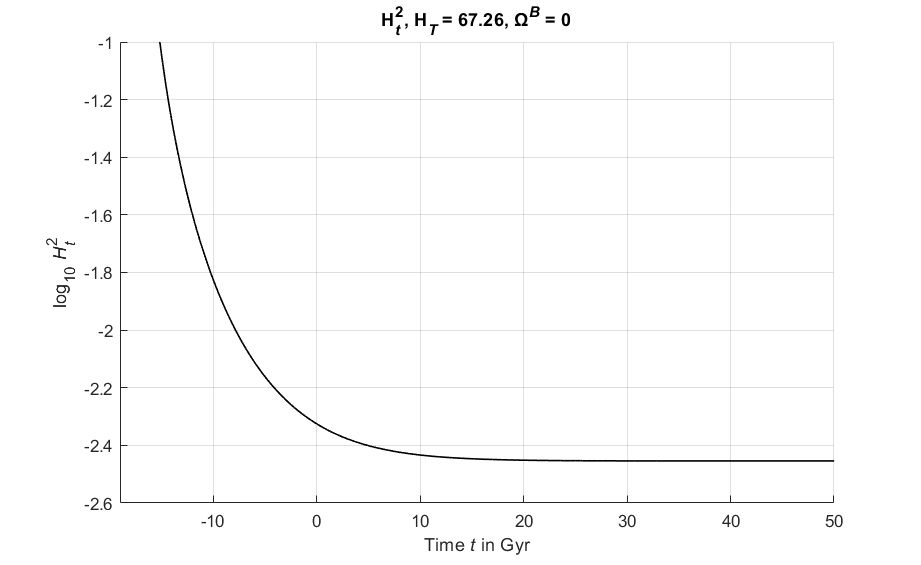

p3 =   Line with properties:

              Color: [0.196078431372549 0.431372549019608 0.901960784313726]
          LineStyle: '-'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×7523 double]
              YData: [1×7523 double]
              ZData: [1×0 double]

  Show all properties


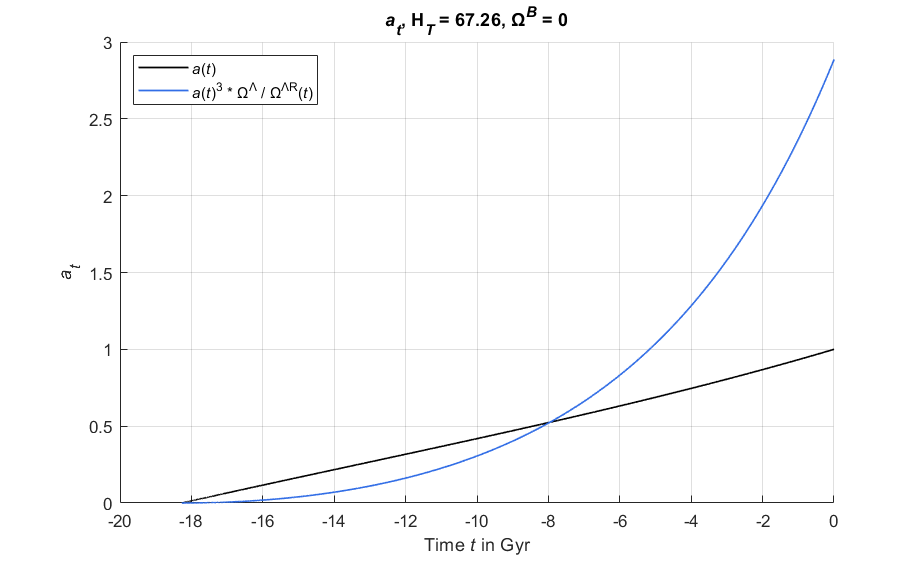

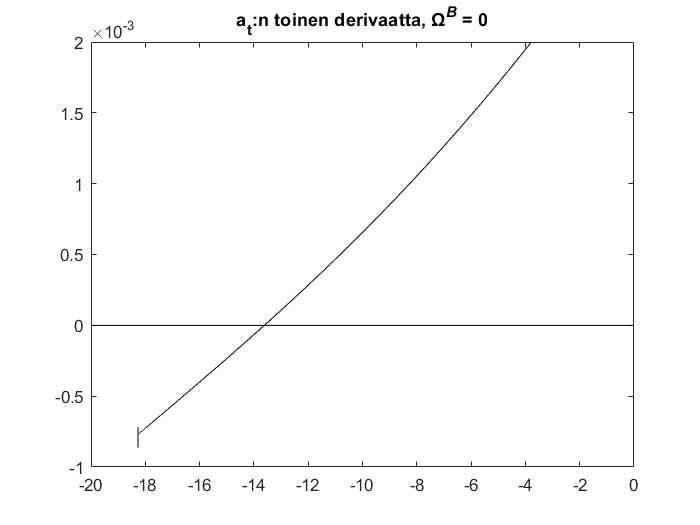

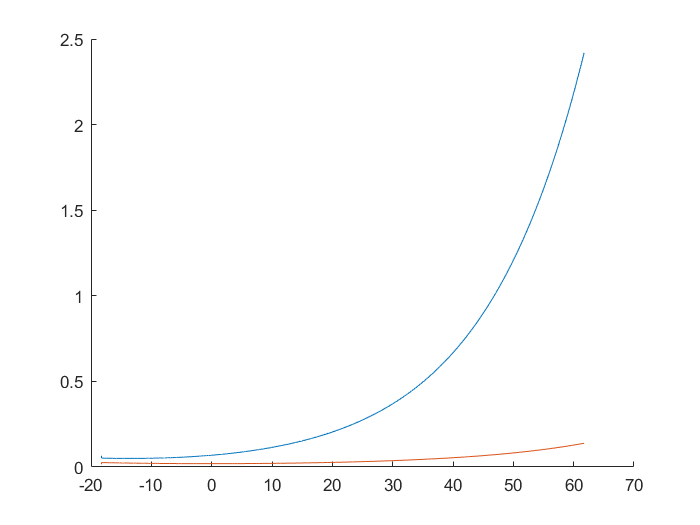

%[a_res, t_res, omega_LR] = LR_model(1,0, 1,true);
%disp(-t_res(1) - 9.70860731629968)

% Figure 1
%final_plot_1()

% Figure 2
%final_plot_50()

% Figure 3
%final_plot_3()

% Figure 4
%final_plot_4()

% Figure 5
%final_plot_many_B()

% Figure 6 along with Tables 1-2
%[omegaB_array, omegaLR, omegaL, T, omegaLR_lin, omegaL_lin] = final_plot_RB();
%print_table_two_col([omegaB_array,omegaLR,omegaL,T])
%print_table_two_col([omegaB_array, omegaLR_lin, omegaL_lin])

% Figure 8
%figure_8()

%fig_9_to_11()

%plot_diff_H() % TURHA NYKYÄÄN -> H1
%plot_diff_H_error()
%plot_diff_Ht()

%plot_diff_H_error_age() % BD = 0.307, semiopt
%plot_diff_Ht_age() % BD = 0.307, semiopt

%plot_diff_H1()

plotBZero()

## Differential Equation Solvers

Let's start with a differential equation (30) and a regular equation (31),

$\left( \frac{\dot{a}}{a} \right)^2 = \frac{H_T^2}{a^3} \Omega^{B+D} +  \frac{H_T^2}{a^3} \alpha \Omega^{\Lambda \text{R}} + H_T^2 \Omega^{\Lambda},$                $\displaystyle \Omega^{\Lambda \text{R}}_t = \frac{H_T \sqrt{\Omega^{\Lambda}}}{a(t)} \int_0^t a(s) \cdot e^{-s \cdot H_T \sqrt{\Omega^{\Lambda}}} \text{d}s.$          (1)

We also have an inital condition $a\left(0\right)=0$. Let's solve for $\dot{a}$,


$$\dot{a} = H_T \sqrt{\frac{1}{a} \Omega^{B+D} +  \frac{\alpha}{a} \Omega^{\Lambda \text{R}} + a^2 \Omega^{\Lambda}}.$$


Let's define $b$ as follows,


$$b(t) = \int_0^t a(s) \cdot e^{-s \cdot H_T \sqrt{\Omega^{\Lambda}}} \text{d}s ~~ \iff ~~\dot{b} = a(s) \cdot e^{-s \cdot H_T \sqrt{\Omega^{\Lambda}}},$$
    
$$b(0)=0$$


With second equation of (1) we have,

$\Omega^{\Lambda \text{R}}_t = \frac{H_T \sqrt{\Omega^{\Lambda}}}{a} b.$          (2)

Let's substitute (2) to the first equation of (1), and we get two differential equations,


$$\dot{a} = H_T \sqrt{\frac{1}{a} \Omega^{B+D} +  \frac{ \alpha H_T \sqrt{\Omega^{\Lambda}}}{a^2}  b + a^2 \Omega^{\Lambda}},$$
                
$$\dot{b} = a \cdot e^{-t \cdot H_T \sqrt{\Omega^{\Lambda}}},$$
    

with initial conditions $a(0) = b(0)=0$. Now we can solve $a$ and $b$ numerically, and finally we can evaluate $\Omega^{\Lambda \text{R}}_t$ with equation (2)

See descriptions of `terminate_T` and `findMax` in the `runge_kutta` algorithm file.

function [a_res, t_res, omega_LR] = LR_model(omegaBD, omegaL, alpha, terminate_T, findMax)
    % Load global variables
    global H_T t_end a0 stepSizeDiff;
    if omegaBD == 0
        t0 = a0 / (alpha^(1/3) * H_T * omegaL^(1/6));
        b0 = t0 * a0;
    else
        t0 = 2/(3 * H_T * sqrt(omegaBD)) * a0^(3/2);
        b0 = t0 * a0;
    end
    
    %t0 = 0;
    %b0 = 0;
    
    [a_res,b_res,t_res] = runge_kutta(@(t, a, b)H_T * sqrt(omegaBD/a + alpha*H_T*sqrt(omegaL)/a^2*b + a^2*omegaL), ...
                                      @(t, a, b)a * exp(-t * H_T * sqrt(omegaL)), ...
                                      a0, b0, t0, ...
                                      t_end, stepSizeDiff, terminate_T, findMax);
    %a_res = a_res(2:end);
    %b_res = b_res(2:end);
    %t_res = t_res(2:end);
    omega_LR = H_T .* sqrt(omegaL) ./ a_res .* b_res;
end

function [a_res, t_res, omega_LR] = LR_model2(omegaBD, omegaL, alpha, terminate_T, findMax)
    global H_T t_end stepSizeDiff
    [F_res,b_res,t_res] = runge_kutta(@(t, a, b)3/2 * H_T * sqrt(omegaBD + alpha*H_T*sqrt(omegaL)*max(b/a^(2/3),0) + a^2*omegaL), ...
                                      @(t, a, b)a^(2/3) * exp(-t * H_T * sqrt(omegaL)), ...
                                      0, 0, 0, ...
                                      t_end, stepSizeDiff*100, terminate_T, findMax);
    F_res = F_res(2:end);
    b_res = b_res(2:end);
    t_res = t_res(2:end);
    a_res = F_res.^(2/3);
    omega_LR = H_T .* sqrt(omegaL) ./ a_res .* b_res;
    omega_LR(1) = 0;
    
end

The Friedmann model's equations are as above, but $\alpha = 0$,

function [a_res, t_res, omega_LR] = F_model(omegaBD, omegaL, terminate_T, findMax)
    [a_res, t_res, omega_LR] = LR_model(omegaBD, omegaL, 0, terminate_T, findMax);
end

Simple function that returns $\Omega^{\Lambda \text{R}}_T$. This function is useful with solvers furher down.

function omegaLR_T = LR_model_omegaLR_T(omegaB,omegaL,alpha)
    [~, ~, omega_LR] = LR_model(omegaB, omegaL, alpha, true, false);
    omegaLR_T = omega_LR(end);
end

## Other Equation Solver Functions

Solves $\Omega^{\Lambda}$ from the flatness algorithm $\Omega^B + \Omega^{\Lambda} + \alpha \Omega^{\Lambda \text{R}}_T = 1$. Evaluation of $ \Omega^{\Lambda \text{R}}_T$ requires integration.

function omegaL = flatness_solve_omegaL(omegaB, alpha)
    global fsolveOptions
    omegaL = fsolve(@(omegaL) alpha*LR_model_omegaLR_T(omegaB, omegaL, alpha) + omegaB + omegaL - 1, ...
                    (1-omegaB)^1.6,... % initial guess
                    fsolveOptions);
end

Same as above, except $a$ is approximated with $a = H_T \, t$. No integration is needed in this algorithm.

function omegaL = flatness_solve_omegaL_linear(omegaB)
    global fsolveOptions
    
    if omegaB == 1
        omegaL = 0;
    else
        omegaL = fsolve(@(omegaL)real(omegaB + (1-exp(-sqrt(omegaL))*(1+sqrt(omegaL)))/sqrt(omegaL) + omegaL) - 1, ...
                        0.7*(1-omegaB), ... % initial guess
                        fsolveOptions);
    end
end

Solves $\alpha$ from flatness equation, $\Omega^B + \Omega^{\Lambda} + \alpha \Omega^{\Lambda \text{R}}_T  + \Omega^D = 1$.

function alpha = flatness_solve_alpha(omegaBD, omegaL)
    global fsolveOptions
    
    alpha = fsolve(@(alpha)omegaBD + omegaL + alpha*LR_model_omegaLR_T(omegaBD, omegaL, alpha) - 1, ...
                    0.2, ... % initial guess
                    fsolveOptions);
end

Solver for optimum $\max_{\Omega^B}{\Omega^{\Lambda \text{R}}_T}$.  $\Omega^{\Lambda}$ is solved from the flatness equation, $\Omega^B + \Omega^{\Lambda} + \Omega^{\Lambda \text{R}}_T = 1$. In the function we solve $\min_{\Omega^B}{(-\Omega^{\Lambda \text{R}}_T)}$

function [omegaLR, omegaB, omegaL] = solve_optimum()
    global fminuncOptions
    
    [omegaB, omegaLRneg] = fminunc(@(omegaB)-LR_model_omegaLR_T(omegaB, flatness_solve_omegaL(omegaB,1), 1), ...
                                    0.0458, ... % initial guess
                                    fminuncOptions);
    omegaLR = -omegaLRneg;
    omegaL = 1 - omegaB - omegaLR;
end

Solver for $\Omega^D$ and $\alpha$, such that age of the universe matches with the Friedmann model, and $\Omega^D + \alpha \Omega^{\Lambda \text{R}}_T = \frac{\Omega^{\Lambda \text{R}}_{T,opt}}{\Omega^B_{opt}} \Omega^B$.

function [omegaD_opt, alpha_opt] = optimizeDalpha()
    global fsolveOptions
    
    x = fsolve(@(x)targetValTime(x(1), x(2)),[0.26,0.083], fsolveOptions);
    omegaD_opt = x(1);
    alpha_opt = x(2);
end

Equations for solving optimal parameters for $\Omega^{\Lambda \text{R}}$-model. Not solvers, just equations, from which we want to solve for zero.

function value = targetTime(alpha, omegaD)
    value = targetTimeLR(alpha, omegaD, 0);
    value = value(1);
end

function value = targetVal(alpha, omegaD)
    value = targetValTime(omegaD, alpha);
    value = value(1);
end

function res = targetTimeLR(alpha, omegaD, alphaLR)
    global benchmarkAge omegaB
    omegaL = flatness_solve_omegaL(omegaB + omegaD, alpha);
    [~, t, omegaLR] = LR_model(omegaB + omegaD, omegaL, alpha, true, false);
    res(1) = t(1) + benchmarkAge;
    res(2) = omegaLR(end)*alpha - alphaLR;
end

function values = targetValTime(omegaD, alpha)
    global omegaLR_opt omegaB_opt omegaB benchmarkAge
    omegaL = 1 - omegaLR_opt/omegaB_opt * omegaB - omegaB;
    [~, t, omega_LR] = LR_model(omegaB + omegaD, omegaL, alpha, true, false);
    values(1) = (omegaD + alpha*omega_LR(end)) / omegaB - omegaLR_opt/omegaB_opt;
    values(2) = t(1) + benchmarkAge;
 end

## Tools for plotting and printing results

This section contains some general functions for plotting. Not relevant to any calculations.

Rounds number to three or four decimals in a string format.

function res = print_num2(x)
    if ~min(x >= 1)
        res = num2str(round(x,4));
    else
        res = num2str(round(x,3));
    end
end

Saves current plot to current Matlab-directory. The function adds a grid and modifies the legend. Optionally adds a box showing $H_T$.

function save_plot(name, leg, plot_HT) % 'leg' stands for legend
    global H_T correction
    figuresize(19.5, 11.96, 'cm')
    grid on
    if ~isa(leg, 'double')
        leg.ItemTokenSize = [30,18]*0.60; % default [30,18]
    end
    if plot_HT
        diff = 3; % gap between legend and H_T box in points
        legPos = leg.Position;
        leg.Units = 'points';
        legPosPt = leg.Position;
        dim = [legPos(1) legPos(2) 0 0];
        str = ['{\itH}_{\itT} = ' num2str(100 * H_T / correction), ' kms^{-1}Mpc^{-1}'];
    end
    
    if plot_HT && leg.Location == "northwest" && leg.Visible == "on"
        vert = 'top';
        horz = 'left';
        dim(2) = (legPosPt(2) - diff) * legPos(2) / legPosPt(2);
    elseif plot_HT && leg.Location == "northwest" && leg.Visible == "off"
        vert = 'top';
        horz = 'left';
        dim = [legPos(1) legPos(2)+legPos(4) 0 0];
    elseif plot_HT && leg.Location == "northeast" && leg.Visible == "on"
        vert = 'top';
        horz = 'right';
        dim = [legPos(1)+legPos(3) legPos(2) 0 0];
        dim(2) = (legPosPt(2) - diff) * legPos(2) / legPosPt(2);
    elseif plot_HT && leg.Location == "southeast" && leg.Visible == "on"
        vert = 'bottom';
        horz = 'right';
        dim = [legPos(1)+legPos(3) legPos(2)+legPos(4) 0 0];
        dim(2) = (legPosPt(2)+legPosPt(4) + diff) * legPos(2) / legPosPt(2);
    else
        vert = 'middle';
        horz = 'center';
    end
    
    if plot_HT
        annotation('textbox',dim,'String',str,'FitBoxToText','on','FontSize',leg.FontSize,'BackgroundColor','white','Margin',3,'VerticalAlignment',vert,'HorizontalAlignment',horz,'LineWidth',leg.LineWidth);
    end
    saveas(gcf, [name, '.pdf'])
end

Creates texts for legends. Input values `NaN`, are not printed.

function res = legend_text(name,R,T,B,D,alpha,L,BDFormat,alphaLRFormat)
    res = [name ': '];
    if ~isnan(R) &&  (alphaLRFormat == "R"|| alphaLRFormat == "R,aR" || alphaLRFormat == "a,R" || alphaLRFormat == "a,R,aR")
        res = [res 'Ω^{ΛR}_{\itT} = ' print_num2(R) ', '];
    end
    if ~isnan(B) && (BDFormat == "B"|| BDFormat == "B,D" || BDFormat == "B,BD" || BDFormat == "B,D,BD")
        res = [res 'Ω^{\itB} = ' print_num2(B) ', '];
    end
    if ~isnan(D) && (BDFormat == "D"|| BDFormat == "B,D" || BDFormat == "D,BD" || BDFormat == "B,D,BD")
        res = [res 'Ω^{\itD} = ' print_num2(D) ', '];
    end
    if ~isnan(B) && ~isnan(D) && (BDFormat == "BD"|| BDFormat == "B,BD" || BDFormat == "D,BD" || BDFormat == "B,D,BD")
        res = [res 'Ω^{{\itB}+{\itD}} = ' print_num2(B+D) ', '];
    end
    if ~isnan(alpha) && (alphaLRFormat == "a"|| alphaLRFormat == "a,aR" || alphaLRFormat == "a,R" || alphaLRFormat == "a,R,aR")
        res = [res '{\itα} = ' print_num2(alpha) ', '];
    end
    if ~isnan(alpha) && ~isnan(R) && (alphaLRFormat == "aR"|| alphaLRFormat == "a,aR" || alphaLRFormat == "R,aR" || alphaLRFormat == "a,R,aR")
        res = [res '{\itα}Ω^{ΛR}_{\itT} = ' print_num2(alpha*R) ', '];
    end
    if ~isnan(L)
        res = [res 'Ω^Λ = ' print_num2(L) ', '];
    end
    if ~isnan(T)
        res = [res '{\itT} = ' print_num2(T) ', '];
    end
    res = res(1:end-2); % removes last ', '
end

Plots a vertical line $x=0$ onto the plot.

function draw_y_axis()
    hold on
    plot([0 0], ylim, '-k', 'LineWidth',0.5,'HandleVisibility','off')
    hold off
end

Prints a two-column table in LaTeX table -format. All data must be numeric. Precision is specified to each column of `matrix`.

function print_table_two_col(matrix)
    et = char(ones(length(matrix(:,1)),1) * ' & ');
    res = char(ones(length(matrix(:,1)),1) * ' ');
    
    for p = 1:(length(matrix(1,:))-1)
        res = [res, print_num2(matrix(:,p)), et];
    end
    
    % The last column without ' & ' at the end
    res = [res, print_num2(matrix(:,end))];
    lines = ceil(length(matrix(:,1))/2);
    
    % If we have uneven number of rows, we need to add a blank row to the end
    if mod(length(matrix(:,1)),2) == 1
        blanks = char(ones(1,length(res(1,:))) * ' ');
    else
        blanks = [];
    end
    
    line = char(ones(lines,1) * ' \\');
    et = char(ones(lines,1) * ' &');
    
    disp([res(1:lines,:), et, [res(lines+1:end,:); blanks], line])
end

Functions for plotting errors between two graphs. Functions make cubic interpolation to the data sets and then calculates the difference at n points.

function [pts,y] = differenceGraphs(n, x1, y1, x2, y2, type)
    tstart = max(min(x1),min(x2));
    tend   = min(max(x1),max(x2));
    pts = linspace(tstart, tend, n);
    if type == "rel" && (abs(interp1(x1,y1,tstart,'pchip')) < 1e-5 || abs(interp1(x1,y1,tstart,'pchip')) > 1e5)
        pts(1) = pts(1)/2 + pts(2)/2;
    end
    if type == "div"
        pts(1) = pts(1)/2 + pts(2)/2;
    end
    vals1 = interp1(x1,y1,pts,'pchip');
    vals2 = interp1(x2,y2,pts,'pchip');
    y = vals2- vals1;
    if type == "rel"
        y = y./vals1;
    end
    if type == "div"
        y = vals2./vals1;
        y(1) = 2*y(1) - y(2);
        pts(1) = 2*pts(1) - pts(2);
    end
    if type == "rel" && (abs(interp1(x1,y1,tstart,'pchip')) < 1e-5 || abs(interp1(x1,y1,tstart,'pchip')) > 1e5)
        y(1) = 2*y(1) - y(2);
        pts(1) = 2*pts(1) - pts(2);
    end
end

Draw annotations with text

function drawPointer(name,x,y,textOffset,textPos,color)
    hold on
    plot([x(1) x(end)],[y(1) y(end)], 'Color', color, 'LineWidth',0.5,'HandleVisibility','off')
    t = text(x(end)+textOffset(1),y(end)+textOffset(end),name,'HorizontalAlignment',textPos,'Rotation',0,'FontSize',9);
    t.Color = color;
    hold off
end

## Figure 1

Plot showing scale factor $a(t)$ of the Friedmann model and $\Lambda \text{R}$-model. Plot shows $t \leq T$.

function final_plot_1()
    % Create new figure frame
    figure; hold on;
    
    % Load global variables
    global omegaB FH_omegaD FH_omegaL
    global F_omegaD F_omegaL
    global LR_omegaL
    global red blue lineWidth
    global H_T
    
    % We only need to plot functions until a(T) = 1,
    % so we stop the differential equation solver at that point
    terminate_T = true;
    findMax = false;
    
    % ΛR-model alpha = 1
    alpha = 1;
    
    % Run the Friedmann model, and plot it
    [aH, tH, omega_LRH] = F_model(omegaB + FH_omegaD, FH_omegaL, terminate_T, findMax);
    pH = plot(tH, aH, '-', 'LineWidth', lineWidth, 'Color', red);
    
    % Run the Friedmann model, and plot it
    [a0, t0, omega_LR0] = F_model(omegaB + F_omegaD, F_omegaL, terminate_T, findMax);
    p0 = plot(t0, a0, '--', 'LineWidth', lineWidth, 'Color', 'k');
    
    % Run the ΛR-model, and plot it
    [a1, t1, omega_LR1] = LR_model2(omegaB, LR_omegaL, alpha, terminate_T, findMax);
    p1 = plot(t1, a1, '-.', 'LineWidth', lineWidth, 'Color', blue);
    
    % Set plot legend
    leg = legend([pH p0 p1],...
        {legend_text('F-model (benchmark)',  omega_LRH(end), -tH(1), omegaB,  FH_omegaD, NaN, FH_omegaL, 'B,D', ''), ...
         legend_text('F-model',  omega_LR0(end), -t0(1), omegaB,  F_omegaD, NaN, F_omegaL, 'BD', ''), ...
         legend_text('ΛR-model', omega_LR1(end), -t1(1), omegaB, NaN,      NaN, LR_omegaL, 'B', '')},...
        'Location',...
        'northwest');
    
    % Set title etc., and save the figure
    xlabel('Time {\itt} in Gyr'); ylabel('Scale factor {\ita}({\itt})')
    axis([-18 1 0 1.1])
    daspect([1 0.1 1]) % Set aspect ratio
    draw_y_axis()
    %save_plot('kuva_1', leg, true)
    
    
    n=10;
    a1(1:n)
    t1(1:n)-t1(1)
    a1(1:n).^(3/2)./(t1(1:n)-t1(1))
    figure;
    plot(t1(1:n)-t1(1), a1(1:n).^(3/2)./(t1(1:n)-t1(1)))
    hold on
    plot([0,t1(n)-t1(1)], [1,1]*3*H_T*sqrt(omegaB)/2)
    title('Yhtälö 2')
    
    b1 = omega_LR1 / (H_T * sqrt(LR_omegaL)) .* a1;
    figure;
    plot(t1(1:n)-t1(1), 1./ (b1(1:n) ./ a1(1:n) ./(t1(1:n)-t1(1))))
    hold on
    plot([0,t1(n)-t1(1)], [1,1])
    title('Yhtälö 1')
end

## Figure 2

function final_plot_50()
    figure; hold on;
    
    global H_T
    global omegaB FH_omegaD FH_omegaL
    global LR_omegaL
    global red blue lineWidth
    
    % Create t-axis points for f and g
    t = linspace(0,51,200);
    
    % Plot f
    plot(t, exp(t/10 * H_T), ':', 'LineWidth', lineWidth, 'Color', 'k');
    % Plot g
    plot(t, exp(t/10 * H_T * sqrt(LR_omegaL)), ':', 'LineWidth', lineWidth, 'Color', 'k');   

Draw annotations for $f$ and $g$.

    tPoint = 22;
    name = '$~g(t) = e^{H_T \sqrt{0.6881}\, t}, \hspace{0.6em} t \geq 0$';
    color = 'k';
    textPos = 'left';
    x = [tPoint,25];
    y = [exp(tPoint/10 * H_T * sqrt(LR_omegaL)),3];
    plot(x,y, 'Color', color, 'LineWidth',0.5,'HandleVisibility','off')
    t = text(x(2),y(2),name,'HorizontalAlignment',textPos,'Rotation',0,'FontSize',13,'Interpreter','latex');
    t.Color = color;
    
    tPoint = 33;
    name = '$f(t) = e^{H_T\, t}, \hspace{0.6em} t \geq 0$~';
    color = 'k';
    textPos = 'right';
    x = [tPoint,27];
    y = [exp(tPoint/10 * H_T),11];
    plot(x,y, 'Color', color, 'LineWidth',0.5,'HandleVisibility','off')
    t = text(x(2),y(2),name,'HorizontalAlignment',textPos,'Rotation',0,'FontSize',13,'Interpreter','latex');
    t.Color = color;

Run and plot F-model and $\Lambda \text{R}$-model

    alpha = 1;
    findMax = false;
    
    % F-model
    [a0, t0, ~] = F_model(omegaB + FH_omegaD, FH_omegaL, false, findMax);
    p0 = plot(t0, a0, '-', 'LineWidth', lineWidth, 'Color', red);
    
    % ΛR-model
    [a1, t1, ~] = LR_model(omegaB, LR_omegaL, alpha, false, findMax);
    p1 = plot(t1, a1, '-.', 'LineWidth', lineWidth, 'Color', blue);

Add legend, axis labels etc. and save the plot

    leg = legend([p0 p1],...
        {legend_text('F-model (benchmark)', NaN,-t0(1),omegaB,FH_omegaD,NaN,FH_omegaL, 'BD', '') ...
         legend_text('ΛR-model',NaN,-t1(1),omegaB, NaN,NaN, LR_omegaL, 'B' , '')},...
        'Location',...
        'northwest');
    
    xlabel('Time {\itt} in Gyr'); ylabel('Scale factor {\ita}({\itt})')
    draw_y_axis()
    axis([-20 50 0 20])
    save_plot('kuva_2A', leg, true)
end

## Figure 3

function final_plot_3()
    figure; hold on;
    
    global omegaB FH_omegaD
    global LR_omegaL
    global red blue lineWidth
    
    % Go pass the point a(T) == 1
    terminate_T = false;
    findMax = true;
    alpha = 1; % For ΛR-model
    
    % Run and plot F-model
    D0 = 1-LR_omegaL-omegaB;
    [~,t0,omega_LR0] = F_model(omegaB + D0, LR_omegaL, terminate_T, findMax);
    p0 = plot(t0, omega_LR0, '-', 'Color', red, 'LineWidth', lineWidth);
    
    % Run and plot ΛR-model
    [~, t1, omega_LR1] = LR_model(omegaB, LR_omegaL, alpha, terminate_T, findMax);
    p1 = plot(t1, omega_LR1, '-.', 'Color', blue, 'LineWidth', lineWidth);
    
    % Find max values and indices of omega_LR
    [F_max_omega_LR, ind0] = max(omega_LR0);
    [LR_max_omega_LR, ind1] = max(omega_LR1);
    
    % Age at the maxima
    F_max_t = t0(ind0);
    LR_max_t = t1(ind1);
    
    % Draw annotations to the max-values:
    % omega_LR annotations
    drawPointer(print_num2(F_max_omega_LR),[F_max_t, 30.3],[F_max_omega_LR,F_max_omega_LR],[.5,0],'left',red)
    drawPointer(print_num2(LR_max_omega_LR),[LR_max_t, 30.3],[LR_max_omega_LR,LR_max_omega_LR],[.5,0],'left',blue)
    
    % t annotations
    drawPointer(print_num2(F_max_t),[F_max_t, F_max_t],[F_max_omega_LR,0.11],[0,-0.006],'left',red)
    drawPointer(print_num2(LR_max_t),[LR_max_t, LR_max_t],[LR_max_omega_LR,0.094],[0,-0.006],'left',blue)
    
    % Create legend
    leg = legend([p0, p1],...
            {[legend_text('Ω^{ΛR}({\itt})', NaN, NaN, omegaB,  FH_omegaD, NaN, LR_omegaL, '', ''), ', {\ita}({\itt}) along F-model trajectory'] ...
             legend_text('Ω^{ΛR}({\itt})',NaN, NaN, omegaB, NaN, NaN, LR_omegaL, '', '')},...
             'Location',...
             'southeast');
    
    % Separation of the omegaLR_T texts
    textOffset = 0.003;
    
    % Find indices where t = T = 0
    [~, F_xAxisIntersect] = min(abs(t0));
    [~, LR_xAxisIntersect] = min(abs(t1));
    
    % Find corresponding omegaLR_Ts and make annotations
    drawPointer(print_num2(omega_LR1(LR_xAxisIntersect)), [0 -12], omega_LR1(LR_xAxisIntersect), [-.5 -textOffset], 'right', blue)
    drawPointer(print_num2(omega_LR0(F_xAxisIntersect)),  [0 -12], omega_LR0(F_xAxisIntersect), [-.5 textOffset], 'right', red)
    
    % Set title etc. and save the figure
    xlabel('Time {\itt} in Gyr'); ylabel('Ω^{ΛR}({\itt})')
    axis([-20 50 0 0.3])
    draw_y_axis()
    save_plot('kuva_3', leg, true)
end

## Figure 4

function final_plot_4()
    figure; hold on;
    
    global omegaB
    global LR_omegaL
    global omegaLR_opt
    global blue lineWidth
    
    terminateT = true;
    findMax = false;
    
    % ΛR-model 1
    omegaD1 = 0.2 - omegaB;
    % Solve alpha from flattness equation:
    alpha1 = flatness_solve_alpha(omegaB + omegaD1, LR_omegaL);
    [a_res, t_res1, omega_LR1] = LR_model(omegaB + omegaD1, LR_omegaL, alpha1, terminateT, findMax);
    p1 = plot(t_res1, a_res, ':','LineWidth',lineWidth,'Color',blue);
    
    % ΛR-model 2
    omegaD2 = 0.27 - omegaB;
    alpha2 = flatness_solve_alpha(omegaB + omegaD2, LR_omegaL);
    [a_res, t_res2, omega_LR2] = LR_model(omegaB + omegaD2, LR_omegaL, alpha2, terminateT, findMax);
    p2 = plot(t_res2, a_res, '-.','LineWidth',lineWidth,'Color',blue);
    
    % ΛR-model 3
    omegaD3 = 0.3 - omegaB;
    alpha3 = flatness_solve_alpha(omegaB + omegaD3, LR_omegaL);
    [a_res, t_res3, omega_LR3] = LR_model(omegaB + omegaD3, LR_omegaL, alpha3, terminateT, findMax);
    p3 = plot(t_res3, a_res, '--','LineWidth',lineWidth,'Color',blue);
    
    % F-model
    [a_res, t_res0, omega_LR0] = F_model(omegaB + omegaLR_opt, LR_omegaL, terminateT, findMax);
    p0 = plot(t_res0, a_res,'-','LineWidth',lineWidth,'Color','k');
    
    leg = legend([p0 p3 p2 p1],...
        {legend_text('F-model',  omega_LR0(end),-t_res0(1),omegaB, omegaLR_opt,NaN, LR_omegaL, 'B,D', ''), ...
         legend_text('ΛR-model', omega_LR3(end),-t_res3(1),omegaB, omegaD3, alpha3, LR_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR2(end),-t_res2(1),omegaB, omegaD2, alpha2, LR_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR1(end),-t_res1(1),omegaB, omegaD1, alpha1, LR_omegaL, 'B,D', 'a,aR')},...
        'Location',...
        'northwest');
    
    xlabel('Time {\itt} in Gyr'); ylabel('Scale factor {\ita}({\itt})')
    axis([-16 1 0 1.1])
    daspect([1 0.1 1])
    draw_y_axis()
    save_plot('kuva_4', leg, true)
end

## Figure 5

function final_plot_many_B()
    figure; hold on;
    
    global omegaB_opt omegaLR_opt
    global red blue
    
    drawNewB(0,red,':',true);
    drawNewB(0.02,red,'--',false);
    
    drawNewB(0.1,blue,'--',true);
    drawNewB(0.2,blue,'-.',true);
    drawNewB(0.4,blue,':',true);
    drawNewB(0.8,blue,':',true);

    drawNewB(omegaB_opt,'k','-',true);
    
    drawPointer(print_num2(omegaLR_opt), [0 -13], [omegaLR_opt omegaLR_opt], [-0.6 0], 'right', 'k')
    
    xlabel('Time {\itt} in Gyr'); ylabel('Ω^{ΛR}({\itt})')
    axis([-20 50 0 0.315])
    draw_y_axis()
    leg = legend('Location','northwest');
    leg.Visible = 'off';
    
    save_plot('kuva_5', leg, true);
end

function p1 = drawNewB(B,color,mark,textB)
    global lineWidth
    
    textRotation = -24;
    L = flatness_solve_omegaL(B, 1);
    [~,t_res,omega_LR] = LR_model(B, L, 1, false, false);
    %(t_res < 50)
    p1 = plot(t_res,omega_LR,mark,'LineWidth',lineWidth);
    p1.Color = color;
    R_omegatext = omega_LR(t_res < 50);
    R_omegatext = R_omegatext(end);
    if textB && B > 0.03
        txt = [' Ω^{\itB} = ', print_num2(B)];
        t = text(50.5,R_omegatext,txt,'HorizontalAlignment','left','Rotation',textRotation,'FontSize',9);
        t.Color = color;
    elseif B == 0
        [~, ind] = min(abs(t_res - 36.5));
        drawPointer(' Ω^{\itB} = 0.0',[t_res(ind),39],[omega_LR(ind),0.027],[0,0],'left',color)
    elseif B == 0.02
        [~, ind] = min(abs(t_res - 39));
        drawPointer(' Ω^{\itB} = 0.02',[t_res(ind),41],[omega_LR(ind),0.04],[0,0],'left',color)
    end
    hold on; 
end

## Figure 6

The function outputs data which can be visualised later.

function [omegaB_table, omegaLR_table, omegaL_table, T_table, omegaLR_table_lin, omegaL_table_lin] = final_plot_RB()
    figure; hold on;
    
    global omegaB_opt omegaB
    global red blue lineWidth
    
    % Create a vector for values of Ω^B, which we want to put in a table
    omegaB_table = [0:0.01:0.04, 0.042, omegaB_opt, omegaB, 0.05, 0.06:0.01:0.1, 0.12:0.02:0.9, 0.91:0.01:1].';
    
    % Add some points for the plot. We'll merge this vector with the
    % values for the table
    omegaB_plot = [0:0.00125:0.04, 0.8:0.05:1].';
    omegaB_plot = sort(unique([omegaB_table; omegaB_plot]));
    
    % Solve for Ω^L with each Ω^B
    % We also calculate another set of Omega^L using the linear model
    omegaL_plot     = arrayfun(@(omegaB) flatness_solve_omegaL(omegaB,1),      omegaB_plot);
    omegaL_plot_lin = arrayfun(@(omegaB) flatness_solve_omegaL_linear(omegaB), omegaB_plot);
    
    % Calculate Ω^ΛR using flatness equation
    omegaLR_plot     = 1 - omegaB_plot - omegaL_plot;
    omegaLR_plot_lin = 1 - omegaB_plot - omegaL_plot_lin;
    
    % Plotting
    p2 = plot(omegaB_plot,omegaLR_plot_lin, '--', 'Color', 'k', 'LineWidth', lineWidth);
    p1 = plot(omegaB_plot,omegaLR_plot,     '-',  'Color', blue, 'LineWidth', lineWidth);
    
    % Find indices of Bopt and omegaB
    [~, indOpt] = min(abs(omegaB_opt - omegaB_plot));
    [~, indOptLeft] = min(abs(0.042 - omegaB_plot));
    [~, indOptRight] = min(abs(0.05 - omegaB_plot));
    
    % Draw red x at Bopt and omegaB
    plot(omegaB_plot([indOptLeft, indOpt, indOptRight]), omegaLR_plot_lin([indOptLeft, indOpt, indOptRight]), '+', 'Color', red, 'LineWidth', lineWidth);
    plot(omegaB_plot([indOptLeft, indOpt, indOptRight]), omegaLR_plot([indOptLeft, indOpt, indOptRight]),     '+', 'Color', red, 'LineWidth', lineWidth);
    plot(omegaB_plot([indOptLeft, indOpt, indOptRight]), [0 0 0],     '+', 'Color', red, 'LineWidth', lineWidth);
    
    drawPointer(print_num2(omegaLR_plot(indOpt)),[omegaB_opt 0.22],[omegaLR_plot(indOpt) omegaLR_plot(indOpt)],[0 0],'left',red)
    drawPointer('Nearly optimal parameter domain [0.042, 0.05]', [omegaB_plot(indOptLeft ) 0.15], [0 0.06], [0.01 0], 'left', red);
    drawPointer('', [omegaB_plot(indOptRight) 0.15], [0 0.06], [0 0], 'left', red);
    
    drawPointer(print_num2(omegaB_opt), [omegaB_opt omegaB_opt], [0 0.075], [-0.03 0.01], 'left', red);
    
    leg = legend([p1 p2],...
        {'Ω^{ΛR}_{\itT}-distribution',...
         'Ω^{ΛR}_{\itT}-distribution with linear approximation for {\ita}({\itt})'},...
        'Location',...
        'northeast');
    
    % Set title etc. and save the figure
    xlabel('Ω^{\itB}'); ylabel('Ω^{ΛR}_{\itT}')
    save_plot('kuva_6', leg, true)
    
    % Let's create the table
    omegaL_table = zeros(length(omegaB_table),1);
    
    for p = 1:length(omegaB_table)
        [~, ind] = min(abs(omegaB_table(p) - omegaB_plot));
        omegaL_table(p) = omegaL_plot(ind);
    end
    
    omegaLR_table = 1 - omegaB_table - omegaL_table;    
    
    T_table = zeros(length(omegaB_table),1);
    for p = 1:length(omegaB_table)
        [~, t_tmp, ~] = LR_model(omegaB_table(p), omegaLR_table(p), 1, true, false);
        T_table(p) = -t_tmp(1);
    end
    
    omegaL_table_lin = zeros(length(omegaB_table),1);
    for p = 1:length(omegaB_table)
        [~, ind] = min(abs(omegaB_table(p) - omegaB_plot));
        omegaL_table_lin(p) = omegaL_plot_lin(ind);
    end
    omegaLR_table_lin = 1 - omegaB_table - omegaL_table_lin;
end

## Figure 8

function figure_8()
    figure; hold on;
    global omegaB FH_omegaD
    global red blue lineWidth
    global fsolveOptions
    
    terminate_T = true;
    findMax = false;
    
    LR1_omegaBD = 0.2;
    LR1_alpha = 0.68;
    LR1_omegaL = flatness_solve_omegaL(LR1_omegaBD, LR1_alpha);
    [a1, t1, omega_LR1] = LR_model(LR1_omegaBD, LR1_omegaL, LR1_alpha, terminate_T, findMax);
    p1 = plot(t1,a1,':','LineWidth', lineWidth, 'Color', 'k');
    
    LR2_omegaBD = 0.27;
    LR2_alpha = 0.3;
    LR2_omegaL = flatness_solve_omegaL(LR2_omegaBD, LR2_alpha);
    [a2, t2, omega_LR2] = LR_model(LR2_omegaBD, LR2_omegaL, LR2_alpha, terminate_T, findMax);
    p2 = plot(t2,a2,':','LineWidth', lineWidth, 'Color', blue);
    
    %LR3_omegaBD = 0.293;
    tmp = fsolve(@(alphaD)targetTimeLR(alphaD(1), alphaD(2), 0.06), [0.23, 0.24], fsolveOptions);
    LR3_alpha = tmp(1);
    LR3_omegaBD = tmp(2) + omegaB;
    LR3_omegaL = flatness_solve_omegaL(LR3_omegaBD, LR3_alpha);
    [a3, t3, omega_LR3] = LR_model(LR3_omegaBD, LR3_omegaL, LR3_alpha, terminate_T, findMax);
    p3 = plot(t3,a3,'-.','LineWidth', lineWidth, 'Color', blue);
    
    %LR4_omegaBD = 0.253;
    tmp = fsolve(@(alphaD)targetTimeLR(alphaD(1), alphaD(2), 0.16), [0.63, 0.2], fsolveOptions);
    LR4_alpha = tmp(1);
    LR4_omegaBD = tmp(2) + omegaB;
    LR4_omegaL = flatness_solve_omegaL(LR4_omegaBD, LR4_alpha);
    [a4, t4, omega_LR4] = LR_model(LR4_omegaBD, LR4_omegaL, LR4_alpha, terminate_T, findMax);
    p4 = plot(t4,a4,'--','LineWidth', lineWidth, 'Color', blue);
    
    H_omegaL = 1-(omegaB+FH_omegaD);
    [aH, tH, omega_LRH] = F_model((omegaB+FH_omegaD), H_omegaL, terminate_T, findMax);
    pH = plot(tH,aH ,'-','LineWidth', lineWidth, 'Color', red);
    
    leg = legend([pH p3 p4 p2 p1],...
        {legend_text('F-model (benchmark)', omega_LRH(end),-tH(1),omegaB, (omegaB+FH_omegaD)-omegaB,NaN, H_omegaL, 'B,D','a,aR'),...
         legend_text('ΛR-model', omega_LR3(end),-t3(1),omegaB, LR3_omegaBD-omegaB,LR3_alpha, LR3_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR4(end),-t4(1),omegaB, LR4_omegaBD-omegaB,LR4_alpha, LR4_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR2(end),-t2(1),omegaB, LR2_omegaBD-omegaB,LR2_alpha, LR2_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR1(end),-t1(1),omegaB, LR1_omegaBD-omegaB,LR1_alpha, LR1_omegaL, 'B,D', 'a,aR')},...
        'Location',...
        'northwest');
    xlabel('Time {\itt} in Gyr'); ylabel('{\ita}({\itt})')
    axis([-16 1 0 1.1])
    daspect([1 0.1 1])
    draw_y_axis()
    save_plot('kuva_8', leg, true)
end

## Figures 9-11

function fig_9_to_11()
    figure; hold on
    global omegaB FH_omegaD
    global omegaD_opt alpha_opt
    global red blue lineWidth
    global fsolveOptions
    
    alphaLR_array = [0.01; 0.02; 0.03];
    res = zeros(2,3);
    
    res(:,1) = fsolve(@(aD)targetTimeLR(aD(1),aD(2),alphaLR_array(1)), [0.1, 0.26], fsolveOptions);
    res(:,2) = fsolve(@(aD)targetTimeLR(aD(1),aD(2),alphaLR_array(2)), [0.1, 0.26], fsolveOptions);
    res(:,3) = fsolve(@(aD)targetTimeLR(aD(1),aD(2),alphaLR_array(3)), [0.1, 0.26], fsolveOptions);
    
    LR2_alpha = res(1,1);
    LR3_alpha = res(1,2);
    LR4_alpha = res(1,3);
    
    LR2_omegaBD = res(2,1) + omegaB;
    LR3_omegaBD = res(2,2) + omegaB;
    LR4_omegaBD = res(2,3) + omegaB;    
    
    LR2_omegaL = flatness_solve_omegaL(LR2_omegaBD, LR2_alpha);
    LR3_omegaL = flatness_solve_omegaL(LR3_omegaBD, LR3_alpha);
    LR4_omegaL = flatness_solve_omegaL(LR4_omegaBD, LR4_alpha);
    
    terminate_T = true;
    findMax = false;
    
    LR_omegaL = flatness_solve_omegaL(omegaB+omegaD_opt, alpha_opt);
    [aOpt, tOpt, omega_LROpt] = LR_model(omegaB + omegaD_opt, LR_omegaL, alpha_opt, true, false);
    p1 = plot(tOpt,aOpt,'-','LineWidth', lineWidth, 'Color', 'k');

    [a2, t2, omega_LR2] = LR_model(LR2_omegaBD, LR2_omegaL, LR2_alpha, terminate_T, findMax);
    p2 = plot(t2,a2,'--','LineWidth', lineWidth, 'Color', blue);
    
    [a3, t3, omega_LR3] = LR_model(LR3_omegaBD, LR3_omegaL, LR3_alpha, terminate_T, findMax);
    p3 = plot(t3,a3,'-.','LineWidth', lineWidth, 'Color', blue);
    
    [a4, t4, omega_LR4] = LR_model(LR4_omegaBD, LR4_omegaL, LR4_alpha, terminate_T, findMax);
    p4 = plot(t4,a4,':','LineWidth', lineWidth, 'Color', blue);
    
    H_omegaL = 1-(omegaB+FH_omegaD);
    [aH, tH, omega_LRH] = F_model((omegaB+FH_omegaD), H_omegaL, terminate_T, findMax);
    pH = plot(tH,aH ,'LineWidth', lineWidth, 'Color', red);
    
    leg = legend([pH p1 p2 p3 p4],...
        {legend_text('F-model (benchmark)', omega_LRH(end),-tH(1),omegaB, (omegaB+FH_omegaD)-omegaB,NaN, H_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model (opt.)', omega_LROpt(end),-tOpt(1),omegaB, omegaD_opt, alpha_opt, LR_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR2(end),-t2(1),omegaB, LR2_omegaBD-omegaB,LR2_alpha, LR2_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR3(end),-t3(1),omegaB, LR3_omegaBD-omegaB,LR3_alpha, LR3_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR4(end),-t4(1),omegaB, LR4_omegaBD-omegaB,LR4_alpha, LR4_omegaL, 'B,D', 'a,aR')},...
        'Location',...
        'northwest');
    xlabel('Time {\itt} in Gyr'); ylabel('{\ita}({\itt})')
    axis([-16 1 0 1.1])
    daspect([1 0.1 1])
    draw_y_axis()
    save_plot('kuva_9', leg, true)
    
    % Set number of points for error plots
    n = 300;
    
    % Absolute errors
    figure; hold on;
    
    [t, v] = differenceGraphs(n, tH, aH, tOpt, aOpt, false);
    pOpt = plot(t,v , '-','LineWidth', lineWidth, 'Color', 'k');
    
    [t, v] = differenceGraphs(n, tH, aH, t2, a2, false);
    p2 = plot(t, v, '--','LineWidth', lineWidth, 'Color', blue);
    
    [t, v] = differenceGraphs(n, tH, aH, t3, a3, false);
    p3 = plot(t, v, '-.','LineWidth', lineWidth, 'Color', blue);
    
    [t, v] = differenceGraphs(n, tH, aH, t4, a4, false);
    p4 = plot(t, v, ':','LineWidth', lineWidth, 'Color', blue);
    
    leg = legend([pOpt p2 p3 p4],...
        {legend_text('ΛR-model (opt.)', omega_LROpt(end),-tOpt(1),omegaB, omegaD_opt,alpha_opt, LR_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR2(end),-t2(1),omegaB, LR2_omegaBD-omegaB,LR2_alpha, LR2_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR3(end),-t3(1),omegaB, LR3_omegaBD-omegaB,LR3_alpha, LR3_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR4(end),-t4(1),omegaB, LR4_omegaBD-omegaB,LR4_alpha, LR4_omegaL, 'B,D', 'a,aR')},...
        'Location',...
        'northeast');
    
    xlabel('Time {\itt} in Gyr'); ylabel('Absolute error')
    axis([-14 0 0 4e-3])
    save_plot('kuva_10', leg, true)
    
    % Relative errors
    figure; hold on;
    
    [t, v] = differenceGraphs(n, tH, aH, tOpt, aOpt, true);
    pOpt = plot(t,v ,     '-','LineWidth', lineWidth, 'Color', 'k');
    
    [t, v] = differenceGraphs(n, tH, aH, t2, a2, true);
    p2 = plot(t, v, '--','LineWidth', lineWidth, 'Color', blue);
    
    [t, v] = differenceGraphs(n, tH, aH, t3, a3, true);
    p3 = plot(t, v, '-.','LineWidth', lineWidth, 'Color', blue);
    
    [t, v] = differenceGraphs(n, tH, aH, t4, a4, true);
    p4 = plot(t, v, ':','LineWidth', lineWidth, 'Color', blue);
    
    leg = legend([pOpt p2 p3 p4],...
        {legend_text('ΛR-model (opt.)', omega_LROpt(end),-tOpt(1),omegaB, omegaD_opt,alpha_opt, LR_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR2(end),-t2(1),omegaB, LR2_omegaBD-omegaB,LR2_alpha, LR2_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR3(end),-t3(1),omegaB, LR3_omegaBD-omegaB,LR3_alpha, LR3_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR4(end),-t4(1),omegaB, LR4_omegaBD-omegaB,LR4_alpha, LR4_omegaL, 'B,D', 'a,aR')},...
        'Location',...
        'northeast');
    
    xlabel('Time {\itt} in Gyr'); ylabel('Relative error')
    axis([-14 0 0 0.018])
    save_plot('kuva_11', leg, true)
    
end
    

## a(t) with different H's

function plot_diff_H()
    % Create new figure frame
    figure; hold on;
    
    % Load global variables
    global omegaB FH_omegaD FH_omegaL
    global red blue lineWidth
    global H_T correction
    
    % We only need to plot functions until a(T) = 1,
    % so we stop the differential equation solver at that point
    terminate_T = true;
    findMax = false;
    
    HH = H_T; DH = FH_omegaD; LH = FH_omegaL;
    
    % Run the Friedmann model
    [aH, tH, omega_LRH] = F_model(omegaB + FH_omegaD, FH_omegaL, terminate_T, findMax);
    pH = plot(tH, aH, '-', 'LineWidth', lineWidth, 'Color', red);
    
    H_T = 0.6750 * correction;
    FH_omegaD = 0.312 - 0.049;
    FH_omegaL = 0.688;
    H0 = H_T; D0 = FH_omegaD; L0 = FH_omegaL;
    
    % Run the Friedmann model
    [a0, t0, omega_LR0] = F_model(omegaB + FH_omegaD, FH_omegaL, terminate_T, findMax);
    p0 = plot(t0, a0, '--', 'LineWidth', lineWidth, 'Color', 'k');
    
    H_T = 0.6785 * correction;
    FH_omegaD = 0.307 - 0.049;
    FH_omegaL = 0.693;
    H1 = H_T; D1 = FH_omegaD; L1 = FH_omegaL;
    
    % Run the Friedmann model
    [a1, t1, omega_LR1] = F_model(omegaB + FH_omegaD, FH_omegaL, terminate_T, findMax);
    p1 = plot(t1, a1, '-.', 'LineWidth', lineWidth, 'Color', blue);
    
    % Set plot legend
    leg = legend([pH p0 p1],...
        {[legend_text('F-model',  omega_LRH(end), -tH(1), omegaB,  DH, NaN, LH, 'BD', ''), ', H_T = ', sprintf('%0.8f',HH)], ...
         [legend_text('F-model',  omega_LR0(end), -t0(1), omegaB,  D0, NaN, L0, 'BD', ''), ', H_T = ', sprintf('%0.8f',H0)], ...
         [legend_text('F-model',  omega_LR1(end), -t1(1), omegaB,  D1, NaN, L1, 'BD', ''), ', H_T = ', sprintf('%0.8f',H1)]},...
        'Location',...
        'northwest');
    
    % Set title etc., and save the figure
    %title(['Figure 1 ', print_today()])
    xlabel('Time {\itt} in Gyr'); ylabel('Scale factor {\ita}({\itt})')
    axis([-14 1 0 1.1])
    daspect([1 0.1 1])
    draw_y_axis()
    save_plot('kuva_12', leg, false)
end

## Different H: a(t) error; abs and rel

function plot_diff_H_error()
    figure; hold on
    global H_T FH_omegaL FH_omegaD omegaB  
    global red blue lineWidth
    global benchmarkAge
    global correction
    
    H_T = 0.6736 * correction;
    H1 = H_T;
    FH_omegaD = 0.315 - omegaB;
    BD1 = FH_omegaD + omegaB;
    FH_omegaL = 0.685;
    
    % Run the Friedmann model
    [a1, t1, ~] = F_model(omegaB + FH_omegaD, FH_omegaL, true, false);
    benchmarkAge = -t1(1);
    
    [omegaD_opt2, alpha_opt2] = optimizeDalpha();
    omegaL = flatness_solve_omegaL(omegaD_opt2 + omegaB, alpha_opt2);
    [a00, t0, LR_00] = LR_model(omegaD_opt2 + omegaB, omegaL, alpha_opt2, true, false);
    LR_00 = LR_00(end);
    LR_00alpha = LR_00*alpha_opt2;
    benchmarkAge = -t0(1);
    
    H_T = 0.6766 * correction;
    H2 = H_T;
    FH_omegaD = 0.311 - 0.049;
    BD2 = FH_omegaD + omegaB;
    FH_omegaL = 0.689;
    
    % Run the Friedmann model
    [a2, t2, ~] = F_model(omegaB + FH_omegaD, FH_omegaL, true, false);
    time2 = -t2(1);
    
    n = 300;
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%% Absolute
    [t, v] = differenceGraphs(n, t0, a00, t1, a1, false);
    pE1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t0, a00, t2, a2, false);
    pE2 = plot(t,v,'-.','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t1, a1, t2, a2, false);
    pF1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', blue);
    
    h1 = plot(0,0,'w');
    h2 = plot(0,0,'w');
    h3 = plot(0,0,'w');
    
    % Set plot legend
    leg = legend([pE1 pE2 pF1 h1 h2 h3],...
        {'Optimal E-m. vs. F-model 1', ...
         'Optimal E-m. vs. F-model 2', ...
         'F-model 1 vs. F-model 2', ...
         ['E-m. (opt.): H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(omegaB+omegaD_opt2)],...
         ['F-m. 1:     H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD1)],...
         ['F-m. 2:     H_T = ' print_num2(100*H2/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD2)],...
        },...
        'Location',...
        'northeast');
    
    % Set title etc., and save the figure
    title('a(t) error')
    xlabel('Time {\itt} in Gyr'); ylabel('Absolute error')
    axis([-14 1 -0.003 0.003])
    save_plot('kuva_a_error_abs', leg, false)
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%% Relative
    figure; hold on;
    
    [t, v] = differenceGraphs(n, t1, a1, t0, a00, true);
    pE1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t2, a2, t0, a00, true);
    pE2 = plot(t,v,'-.','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t1, a1, t2, a2, true);
    pF1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', blue);
    
    h1 = plot(0,0,'w');
    h2 = plot(0,0,'w');
    h3 = plot(0,0,'w');
    
    % Set plot legend
    leg = legend([pE1 pE2 pF1 h1 h2 h3],...
        {'Optimal E-m. vs. F-model 1', ...
         'Optimal E-m. vs. F-model 2', ...
         'F-model 1 vs. F-model 2', ...
         ['E-m. (opt.): H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(omegaB+omegaD_opt2)],...
         ['F-m. 1:     H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD1)],...
         ['F-m. 2:     H_T = ' print_num2(100*H2/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD2)],...
        },...
        'Location',...
        'northeast');
    
    % Set title etc., and save the figure
    title('a(t) error')
    xlabel('Time {\itt} in Gyr'); ylabel('Relative error')
    axis([-14 1 -0.014 0.014])
    save_plot('kuva_a_error_rel', leg, false)
    H_T = 0.6726 * correction;
end

## Different H: a(t) error with age opt E-m.; abs and rel

function plot_diff_H_error_age()
    figure; hold on
    global H_T FH_omegaL FH_omegaD omegaB  
    global red blue lineWidth
    global benchmarkAge correction
    global fsolveOptions
    
    H_T = 0.6736 * correction;
    H1 = H_T;
    FH_omegaD = 0.315 - omegaB;
    BD1 = FH_omegaD + omegaB;
    FH_omegaL = 0.685;
    
    % Run the Friedmann model
    [a1, t1, ~] = F_model(omegaB + FH_omegaD, FH_omegaL, true, false);
    benchmarkAge = -t1(1);
    
    omegaD_opt2 = 0.307 - omegaB;
    alpha_opt2 = fsolve(@(alpha)[1 0]*targetTimeLR(alpha, omegaD_opt2, 0).', 0.2, fsolveOptions);
    omegaL = flatness_solve_omegaL(omegaD_opt2 + omegaB, alpha_opt2);
    [a00, t0, LR_00] = LR_model(omegaD_opt2 + omegaB, omegaL, alpha_opt2, true, false);
    LR_00 = LR_00(end);
    LR_00alpha = LR_00*alpha_opt2;
    benchmarkAge = -t0(1);
    
    H_T = 0.6766 * correction;
    H2 = H_T;
    FH_omegaD = 0.311 - 0.049;
    BD2 = FH_omegaD + omegaB;
    FH_omegaL = 0.689;
    
    % Run the Friedmann model
    [a2, t2, ~] = F_model(omegaB + FH_omegaD, FH_omegaL, true, false);
    time2 = -t2(1);
    
    n = 300;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%% Fixed pt. Absolute
    [t, v] = differenceGraphs(n, t1, a1, t1, a1, "abs");
    pE1 = plot(t,v,'-.','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t1, a1, t0, a00, "abs");
    pE2 = plot(t,v,'-','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t1, a1, t2, a2, "abs");
    pF1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', blue);
    
    h1 = plot(0,0,'w');
    h2 = plot(0,0,'w');
    h3 = plot(0,0,'w');
    
    % Set plot legend
    leg = legend([pE1 pE2 pF1 h1 h2 h3],...
        {'F-m. 1 − F-m. 1', ...
         'Opt. E-m. − F-m. 1', ...
         'F-m. 2 − F-m. 1', ...
         ['E-m. (age opt.): H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(omegaB+omegaD_opt2)],...
         ['F-m. 1:     H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD1)],...
         ['F-m. 2:     H_T = ' print_num2(100*H2/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD2)],...
        },...
        'Location',...
        'northeast');
    
    % Set title etc., and save the figure
    title('a(t) error')
    xlabel('Time {\itt} in Gyr'); ylabel('Absolute error')
    axis([-14 1 -0.003 0.003])
    save_plot('kuva_a_error_abs_2', leg, false)
    
    figure; hold on;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%% Absolute
    [t, v] = differenceGraphs(n, t0, a00, t1, a1, "abs");
    pE1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t0, a00, t2, a2, "abs");
    pE2 = plot(t,v,'-.','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t1, a1, t2, a2, "abs");
    pF1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', blue);
    
    h1 = plot(0,0,'w');
    h2 = plot(0,0,'w');
    h3 = plot(0,0,'w');
    
    % Set plot legend
    leg = legend([pE1 pE2 pF1 h1 h2 h3],...
        {'Optimal E-m. vs. F-model 1', ...
         'Optimal E-m. vs. F-model 2', ...
         'F-model 1 vs. F-model 2', ...
         ['E-m. (age opt.): H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(omegaB+omegaD_opt2)],...
         ['F-m. 1:     H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD1)],...
         ['F-m. 2:     H_T = ' print_num2(100*H2/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD2)],...
        },...
        'Location',...
        'northeast');
    
    % Set title etc., and save the figure
    title('a(t) error')
    xlabel('Time {\itt} in Gyr'); ylabel('Absolute error')
    axis([-14 1 -0.003 0.003])
    save_plot('kuva_a_error_abs', leg, false)
    
    figure; hold on;
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%% Divided
    [t, v] = differenceGraphs(n, t0, a00, t1, a1, "div");
    pE1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t0, a00, t2, a2, "div");
    pE2 = plot(t,v,'-.','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t1, a1, t2, a2, "div");
    pF1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', blue);
    
    h1 = plot(0,0,'w');
    h2 = plot(0,0,'w');
    h3 = plot(0,0,'w');
    
    % Set plot legend
    leg = legend([pE1 pE2 pF1 h1 h2 h3],...
        {'F-model 1 / Optimal E-m.', ...
         'F-model 2 / Optimal E-m.', ...
         'F-model 2 / F-model 1', ...
         ['E-m. (age opt.): H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(omegaB+omegaD_opt2)],...
         ['F-m. 1:     H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD1)],...
         ['F-m. 2:     H_T = ' print_num2(100*H2/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD2)],...
        },...
        'Location',...
        'northeast');
    
    % Set title etc., and save the figure
    title('a(t) error')
    xlabel('Time {\itt} in Gyr');
    axis([-14 1 0.985 1.015])
    save_plot('kuva_a_error_div', leg, false)
    
    figure; hold on;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%% Fixed pt. Rel
    [t, v] = differenceGraphs(n, t1, a1, t1, a1, "rel");
    pE1 = plot(t,v,'-.','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t1, a1, t0, a00, "rel");
    pE2 = plot(t,v,'-','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t1, a1, t2, a2, "rel");
    pF1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', blue);
    
    h1 = plot(0,0,'w');
    h2 = plot(0,0,'w');
    h3 = plot(0,0,'w');
    
    % Set plot legend
    leg = legend([pE1 pE2 pF1 h1 h2 h3],...
        {'(F-m. 1 − F-m. 1) / F-m. 1', ...
         '(Opt. E-m. − F-m. 1) / F-m. 1', ...
         '(F-m. 2 − F-m. 1) / F-m. 1', ...
         ['E-m. (age opt.): H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(omegaB+omegaD_opt2)],...
         ['F-m. 1:     H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD1)],...
         ['F-m. 2:     H_T = ' print_num2(100*H2/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD2)],...
        },...
        'Location',...
        'northeast');
    
    % Set title etc., and save the figure
    title('a(t) error')
    xlabel('Time {\itt} in Gyr'); ylabel('Relative error')
    axis([-14 1 -0.012 0.008])
    save_plot('kuva_a_error_rel_2', leg, false)
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%% Relative
    figure; hold on;
    
    [t, v] = differenceGraphs(n, t1, a1, t0, a00, "rel");
    pE1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t2, a2, t0, a00, "rel");
    pE2 = plot(t,v,'-.','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t1, a1, t2, a2, "rel");
    pF1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', blue);
    
    h1 = plot(0,0,'w');
    h2 = plot(0,0,'w');
    h3 = plot(0,0,'w');
    
    % Set plot legend
    leg = legend([pE1 pE2 pF1 h1 h2 h3],...
        {'Optimal E-m. vs. F-model 1', ...
         'Optimal E-m. vs. F-model 2', ...
         'F-model 1 vs. F-model 2', ...
         ['E-m. (age opt.): H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(omegaB+omegaD_opt2)],...
         ['F-m. 1:     H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD1)],...
         ['F-m. 2:     H_T = ' print_num2(100*H2/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD2)],...
        },...
        'Location',...
        'northeast');
    
    % Set title etc., and save the figure
    title('a(t) error')
    xlabel('Time {\itt} in Gyr'); ylabel('Relative error')
    axis([-14 1 -0.014 0.014])
    save_plot('kuva_a_error_rel', leg, false)
    H_T = 0.6726 * correction;
end

## Plotting H(t)

 
function plot_diff_Ht()
    figure; hold on
    global H_T FH_omegaL FH_omegaD omegaB  
    global red blue lineWidth
    global benchmarkAge
    global correction
    
    H_T = 0.6736 * correction;
    H1 = H_T;
    FH_omegaD = 0.315 - omegaB;
    BD1 = FH_omegaD + omegaB;
    FH_omegaL = 0.685;
    
    % Run the Friedmann model
    [a1, t1, LR_F1] = F_model(omegaB + FH_omegaD, FH_omegaL, true, false);
    benchmarkAge = -t1(1);
    a_dot = @(t, a, b)H_T * sqrt((FH_omegaD + omegaB)/a + 0*H_T*sqrt(FH_omegaL)/a^2*b + a^2*FH_omegaL);
    b = LR_F1 / (H_T * sqrt(FH_omegaL)) .* a1;
    H_t_F1 = arrayfun(@(p)a_dot(t1(p), a1(p), b(p)), 1:length(a1)).' ./ a1;
    
    [omegaD_opt2, alpha_opt2] = optimizeDalpha();
    omegaL = flatness_solve_omegaL(omegaD_opt2 + omegaB, alpha_opt2);
    [a00, t0, LR_00] = LR_model(omegaD_opt2 + omegaB, omegaL, alpha_opt2, true, false);
    a_dot = @(t, a, b)H_T * sqrt((omegaD_opt2 + omegaB)/a + alpha_opt2*H_T*sqrt(omegaL)/a^2*b + a^2*omegaL);
    b = LR_00 / (H_T * sqrt(omegaL)) .* a00;
    H_t_00 = arrayfun(@(p)a_dot(t0(p), a00(p), b(p)), 1:length(a00)).' ./ a00;
    
    H_T = 0.6766 * correction;
    H2 = H_T;
    FH_omegaD = 0.311 - omegaB;
    BD2 = FH_omegaD + omegaB;
    FH_omegaL = 0.689;
    
    % Run the Friedmann model
    [a2, t2, LR_F2] = F_model(omegaB + FH_omegaD, FH_omegaL, true, false);
    time2 = -t2(1);
    a_dot = @(t, a, b)H_T * sqrt((FH_omegaD + omegaB)/a + 0*H_T*sqrt(FH_omegaL)/a^2*b + a^2*FH_omegaL);
    b = LR_F2 / (H_T * sqrt(FH_omegaL)) .* a2;
    H_t_F2 = arrayfun(@(p)a_dot(t2(p), a2(p), b(p)), 1:length(a2)).' ./ a2;
    
    p0 = plot(t0, log10(H_t_00), '-','LineWidth', lineWidth, 'Color', red);
    p1 = plot(t1, log10(H_t_F1), '-.','LineWidth', lineWidth, 'Color', blue);
    p2 = plot(t2, log10(H_t_F2), '--','LineWidth', lineWidth, 'Color', blue);
    
    xlabel('Time {\itt} in Gyr'); ylabel('log_{10} {\itH}_{\itt}')
    leg = legend([p0 p1 p2],...
        {['E-m. (age opt.): H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(omegaB+omegaD_opt2)], ...
         ['F-m. 1:     H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD1)], ...
         ['F-m. 2:     H_T = ' print_num2(100*H2/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD2)], ...
        },...
        'Location',...
        'northeast');
    title('H_t')
    save_plot('kuva_H_t', leg, false)
    
    
    %%%%%%%%%
    figure; hold on;
    n = 400;
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%% Absolute
    [t, v] = differenceGraphs(n, t0, H_t_00, t1, H_t_F1, false);
    pE1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t0, H_t_00, t2, H_t_F2, false);
    pE2 = plot(t,v,'-.','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t1, H_t_F1, t2, H_t_F2, false);
    pF1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', blue);
    
    h1 = plot(0,0,'w');
    h2 = plot(0,0,'w');
    h3 = plot(0,0,'w');
    
    % Set plot legend
    leg = legend([pE1 pE2 pF1 h1 h2 h3],...
        {'Optimal E-m. vs. F-model 1', ...
         'Optimal E-m. vs. F-model 2', ...
         'F-model 1 vs. F-model 2', ...
         ['E-m. (opt.): H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(omegaB+omegaD_opt2)],...
         ['F-m. 1:     H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD1)],...
         ['F-m. 2:     H_T = ' print_num2(100*H2/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD2)],...
        },...
        'Location',...
        'northeast');
    
    % Set title etc., and save the figure
    xlabel('Time {\itt} in Gyr'); ylabel('Absolute error')
    title('H_t error')
    axis([-14 1 -0.025 0.025])
    save_plot('kuva_H_t_error_abs', leg, false)
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%% Relative
    figure; hold on;
    
    [t, v] = differenceGraphs(n, t1, H_t_F1, t0, H_t_00, true);
    pE1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t2, H_t_F2, t0, H_t_00, true);
    pE2 = plot(t,v,'-.','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t1, H_t_F1, t2, H_t_F2, true);
    pF1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', blue);
    
    h1 = plot(0,0,'w');
    h2 = plot(0,0,'w');
    h3 = plot(0,0,'w');
    
    % Set plot legend
    leg = legend([pE1 pE2 pF1 h1 h2 h3],...
        {'Optimal E-m. vs. F-model 1', ...
         'Optimal E-m. vs. F-model 2', ...
         'F-model 1 vs. F-model 2', ...
         ['E-m. (opt.): H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(omegaB+omegaD_opt2)],...
         ['F-m. 1:     H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD1)],...
         ['F-m. 2:     H_T = ' print_num2(100*H2/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD2)],...
        },...
        'Location',...
        'northeast');
    
    % Set title etc., and save the figure
    xlabel('Time {\itt} in Gyr'); ylabel('Relative error')
    title('H_t error')
    axis([-14 1 -0.012 0.012])
    save_plot('kuva_H_t_error_rel', leg, false)
    H_T = 0.6726 * correction;
    
end

## Plotting H(t), age opt E-m.

 
function plot_diff_Ht_age()
    figure; hold on
    global H_T FH_omegaL FH_omegaD omegaB  
    global red blue lineWidth
    global benchmarkAge correction
    global fsolveOptions
    
    H_T = 0.6736 * correction;
    H1 = H_T;
    FH_omegaD = 0.315 - omegaB;
    BD1 = FH_omegaD + omegaB;
    FH_omegaL = 0.685;
    
    % Run the Friedmann model
    [a1, t1, LR_F1] = F_model(omegaB + FH_omegaD, FH_omegaL, true, false);
    benchmarkAge = -t1(1);
    a_dot = @(t, a, b)H_T * sqrt((FH_omegaD + omegaB)/a + 0*H_T*sqrt(FH_omegaL)/a^2*b + a^2*FH_omegaL);
    b = LR_F1 / (H_T * sqrt(FH_omegaL)) .* a1;
    H_t_F1 = arrayfun(@(p)a_dot(t1(p), a1(p), b(p)), 1:length(a1)).' ./ a1;
    
    omegaD_opt2 = 0.307 - omegaB;
    alpha_opt2 = fsolve(@(alpha)[1 0]*targetTimeLR(alpha, omegaD_opt2, 0).', 0.2, fsolveOptions);
    omegaL = flatness_solve_omegaL(omegaD_opt2 + omegaB, alpha_opt2);
    [a00, t0, LR_00] = LR_model(omegaD_opt2 + omegaB, omegaL, alpha_opt2, true, false);
    a_dot = @(t, a, b)H_T * sqrt((omegaD_opt2 + omegaB)/a + alpha_opt2*H_T*sqrt(omegaL)/a^2*b + a^2*omegaL);
    b = LR_00 / (H_T * sqrt(omegaL)) .* a00;
    H_t_00 = arrayfun(@(p)a_dot(t0(p), a00(p), b(p)), 1:length(a00)).' ./ a00;
    
    H_T = 0.6766 * correction;
    H2 = H_T;
    FH_omegaD = 0.311 - omegaB;
    BD2 = FH_omegaD + omegaB;
    FH_omegaL = 0.689;
    
    % Run the Friedmann model
    [a2, t2, LR_F2] = F_model(omegaB + FH_omegaD, FH_omegaL, true, false);
    time2 = -t2(1);
    a_dot = @(t, a, b)H_T * sqrt((FH_omegaD + omegaB)/a + 0*H_T*sqrt(FH_omegaL)/a^2*b + a^2*FH_omegaL);
    b = LR_F2 / (H_T * sqrt(FH_omegaL)) .* a2;
    H_t_F2 = arrayfun(@(p)a_dot(t2(p), a2(p), b(p)), 1:length(a2)).' ./ a2;
    
    p0 = plot(t0, log10(H_t_00), '-','LineWidth', lineWidth, 'Color', red);
    p1 = plot(t1, log10(H_t_F1), '-.','LineWidth', lineWidth, 'Color', blue);
    p2 = plot(t2, log10(H_t_F2), '--','LineWidth', lineWidth, 'Color', blue);
    
    xlabel('Time {\itt} in Gyr'); ylabel('log_{10} {\itH}_{\itt}')
    leg = legend([p0 p1 p2],...
        {['E-m. (opt.): H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(omegaB+omegaD_opt2)], ...
         ['F-m. 1:     H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD1)], ...
         ['F-m. 2:     H_T = ' print_num2(100*H2/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD2)], ...
        },...
        'Location',...
        'northeast');
    title('H_t')
    %save_plot('kuva_H_t', leg, false)
    
    
    %%%%%%%%%
    figure; hold on;
    n = 400;
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%% Bechmark fixed absolute
    [t, v] = differenceGraphs(n, t1, H_t_F1, t1, H_t_F1, "abs");
    pE1 = plot(t,v,'-.','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t1, H_t_F1, t0, H_t_00, "abs");
    pE2 = plot(t,v,'-','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t1, H_t_F1, t2, H_t_F2, "abs");
    pF1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', blue);
    
    h1 = plot(0,0,'w');
    h2 = plot(0,0,'w');
    h3 = plot(0,0,'w');
    
    % Set plot legend
    leg = legend([pE1 pE2 pF1 h1 h2 h3],...
        {'F-m. 1 − F-m. 1', ...
         'Opt. E-m. − F-m. 1', ...
         'F-m. 2 − F-m. 1', ...
         ['E-m. (age opt.): H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(omegaB+omegaD_opt2)],...
         ['F-m. 1:     H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD1)],...
         ['F-m. 2:     H_T = ' print_num2(100*H2/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD2)],...
        },...
        'Location',...
        'northeast');
    
    % Set title etc., and save the figure
    xlabel('Time {\itt} in Gyr'); ylabel('Absolute error')
    title('H_t error')
    axis([-14 1 -0.01 0.03])
    %save_plot('kuva_H_t_error_abs_2', leg, false)
    
    figure; hold on;
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%% Absolute
    [t, v] = differenceGraphs(n, t0, H_t_00, t1, H_t_F1, "abs");
    pE1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t0, H_t_00, t2, H_t_F2, "abs");
    pE2 = plot(t,v,'-.','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t1, H_t_F1, t2, H_t_F2, "abs");
    pF1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', blue);
    
    h1 = plot(0,0,'w');
    h2 = plot(0,0,'w');
    h3 = plot(0,0,'w');
    
    % Set plot legend
    leg = legend([pE1 pE2 pF1 h1 h2 h3],...
        {'Optimal E-m. vs. F-model 1', ...
         'Optimal E-m. vs. F-model 2', ...
         'F-model 1 vs. F-model 2', ...
         ['E-m. (age opt.): H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(omegaB+omegaD_opt2)],...
         ['F-m. 1:     H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD1)],...
         ['F-m. 2:     H_T = ' print_num2(100*H2/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD2)],...
        },...
        'Location',...
        'northeast');
    
    % Set title etc., and save the figure
    xlabel('Time {\itt} in Gyr'); ylabel('Absolute error')
    title('H_t error')
    axis([-14 1 -0.025 0.025])
    %save_plot('kuva_H_t_error_abs', leg, false)
    
    figure; hold on;
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%% Divided
    [t, v] = differenceGraphs(n, t0, H_t_00, t1, H_t_F1, "div");
    pE1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t0, H_t_00, t2, H_t_F2, "div");
    pE2 = plot(t,v,'-.','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t1, H_t_F1, t2, H_t_F2, "div");
    pF1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', blue);
    
    h1 = plot(0,0,'w');
    h2 = plot(0,0,'w');
    h3 = plot(0,0,'w');
    
    % Set plot legend
    leg = legend([pE1 pE2 pF1 h1 h2 h3],...
        {'F-model 1 / Optimal E-m.', ...
         'F-model 2 / Optimal E-m.', ...
         'F-model 2 / F-model 1', ...
         ['E-m. (age opt.): H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(omegaB+omegaD_opt2)],...
         ['F-m. 1:     H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD1)],...
         ['F-m. 2:     H_T = ' print_num2(100*H2/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD2)],...
        },...
        'Location',...
        'northeast');
    
    % Set title etc., and save the figure
    xlabel('Time {\itt} in Gyr');
    title('H_t error')
    axis([-14 1 0.99 1.03])
    %save_plot('kuva_H_t_error_div', leg, false)
    
    figure; hold on;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%% Bechmark fixed relative
    [t, v] = differenceGraphs(n, t1, H_t_F1, t1, H_t_F1, "rel");
    pE1 = plot(t,v,'-.','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t1, H_t_F1, t0, H_t_00, "rel");
    pE2 = plot(t,v,'-','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t1, H_t_F1, t2, H_t_F2, "rel");
    pF1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', blue);
    
    h1 = plot(0,0,'w');
    h2 = plot(0,0,'w');
    h3 = plot(0,0,'w');
    
    % Set plot legend
    leg = legend([pE1 pE2 pF1 h1 h2 h3],...
        {'(F-m. 1 − F-m. 1) / F-m. 1', ...
         '(Opt. E-m. − F-m. 1) / F-m. 1', ...
         '(F-m. 2 − F-m. 1) / F-m. 1', ...
         ['E-m. (age opt.): H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(omegaB+omegaD_opt2)],...
         ['F-m. 1:     H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD1)],...
         ['F-m. 2:     H_T = ' print_num2(100*H2/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD2)],...
        },...
        'Location',...
        'northeast');
    
    % Set title etc., and save the figure
    xlabel('Time {\itt} in Gyr'); ylabel('Relative error')
    title('H_t error')
    axis([-14 1 -0.002 0.014])
    %save_plot('kuva_H_t_error_rel_2', leg, false)
    
    figure; hold on;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%% Relative
    
    [t, v] = differenceGraphs(n, t1, H_t_F1, t0, H_t_00, "rel");
    pE1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t2, H_t_F2, t0, H_t_00, "rel");
    pE2 = plot(t,v,'-.','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t1, H_t_F1, t2, H_t_F2, "rel");
    pF1 = plot(t,v,'-','LineWidth', lineWidth, 'Color', blue);
    
    h1 = plot(0,0,'w');
    h2 = plot(0,0,'w');
    h3 = plot(0,0,'w');
    
    % Set plot legend
    leg = legend([pE1 pE2 pF1 h1 h2 h3],...
        {'Optimal E-m. vs. F-model 1', ...
         'Optimal E-m. vs. F-model 2', ...
         'F-model 1 vs. F-model 2', ...
         ['E-m. (age opt.): H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(omegaB+omegaD_opt2)],...
         ['F-m. 1:     H_T = ' print_num2(100*H1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD1)],...
         ['F-m. 2:     H_T = ' print_num2(100*H2/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD2)],...
        },...
        'Location',...
        'northeast');
    
    % Set title etc., and save the figure
    xlabel('Time {\itt} in Gyr'); ylabel('Relative error')
    title('H_t error')
    axis([-14 1 -0.012 0.012])
    %save_plot('kuva_H_t_error_rel', leg, false)
    H_T = 0.6726 * correction;
    
end

## Many H's with error

function plot_diff_H1()
    global H_T correction omegaB omegaD_opt alpha_opt
    global red blue lineWidth
    H_T = 0.6715*correction;
    H_F0 = H_T;
    BD_F0 = 0.317;
    L_F0 = 0.683;
    [a_0, t0, ~] = F_model(BD_F0, L_F0, true, false);
    
    L_opt = flatness_solve_omegaL(omegaB+omegaD_opt, alpha_opt);
    [a_opt, topt, ~] = LR_model(omegaB+omegaD_opt, L_opt, alpha_opt, true, false);
    
    H_F1 = 0.6750 * correction;
    H_T = H_F1;
    BD_F1 = 0.312;
    L_F1 = 0.688;
    [a_1, t1, ~] = F_model(BD_F1, L_F1, true, false);
    
    H_F2 = 0.6785 * correction;
    H_T = H_F2;
    BD_F2 = 0.307;
    L_F2 = 0.693;
    [a_2, t2, ~] = F_model(BD_F2, L_F2, true, false);
    
    n = 300;
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%% Absolute
    figure; hold on
    [t, v] = differenceGraphs(n, t0, a_0, topt, a_opt, false);
    pEF0 = plot(t,v,'-','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t1, a_1, topt, a_opt, false);
    pEF1 = plot(t,v,'-.','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t2, a_2, topt, a_opt, false);
    pEF2 = plot(t,v,'--','LineWidth', lineWidth, 'Color', red);
    
    [t, v] = differenceGraphs(n, t0, a_0, t1, a_1, false);
    pFF1 = plot(t,v,'-.','LineWidth', lineWidth, 'Color', blue);
    
    [t, v] = differenceGraphs(n, t0, a_0, t2, a_2, false);
    pFF2 = plot(t,v,'--','LineWidth', lineWidth, 'Color', blue);
    
    h1 = plot(0, 0, 'white');
    h2 = plot(0, 0, 'white');
    h3 = plot(0, 0, 'white');
    h4 = plot(0, 0, 'white');
    
    % Set plot legend
    leg = legend([pEF0 pEF1 pEF2 pFF1 pFF2 h1 h2 h3 h4],...
        {'Optimal E-m. vs. benchmark F-model', ...
         'Optimal E-m. vs. F-model 1', ...
         'Optimal E-m. vs. F-model 2', ...
         'Benchmark F-model vs. F-model 1', ...
         'Benchmark F-model vs. F-model 2', ...
         ['E-m. (opt.):    H_T = ' print_num2(100*H_F0/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(omegaB+omegaD_opt)],...
         ['F-m. (benchm.): H_T = ' print_num2(100*H_F0/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD_F0)],...
         ['F-model 1:      H_T = ' print_num2(100*H_F1/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD_F1)],...
         ['F-model 2:      H_T = ' print_num2(100*H_F2/correction) ', Ω^{{\itB}+{\itD}} = ' print_num2(BD_F2)],...
        },...
        'Location',...
        'northeast');
    
    % Set title etc., and save the figure
    xlabel('Time {\itt} in Gyr'); ylabel('Absolute error')
    axis([-14 1 -0.005 0.005])
    save_plot('kuva_a_error_abs_x', leg, false)
    
    %%%%%%%%%%%%%%%% a's
    figure; hold on;
    p1 = plot(t0, a_0, '-' ,'LineWidth', lineWidth, 'Color', red);
    p2 = plot(t1, a_1, '--' ,'LineWidth', lineWidth, 'Color', 'k');
    p3 = plot(t2, a_2, '-.' ,'LineWidth', lineWidth, 'Color', blue);
    
    leg = legend([p1 p2 p3],...
        {[legend_text('F-model',  NaN, -t0(1), BD_F0,  0, NaN, L_F0, 'BD', ''), ', H_T = ', print_num2(100*H_F0/correction)], ...
         [legend_text('F-model',  NaN, -t1(1), BD_F1,  0, NaN, L_F1, 'BD', ''), ', H_T = ', print_num2(100*H_F1/correction)], ...
         [legend_text('F-model',  NaN, -t2(1), BD_F2,  0, NaN, L_F2, 'BD', ''), ', H_T = ', print_num2(100*H_F2/correction)], ...
        },...
        'Location',...
        'northwest');
    
    xlabel('Time {\itt} in Gyr'); ylabel('Scale factor {\ita}({\itt})')
    axis([-14 1 0 1])
    draw_y_axis()
    save_plot('kuva_a_x', leg, false)
end

function plotBZero()
    figure; hold on
    global stepSizeDiff
    global H_T FH_omegaL FH_omegaD
    global a0;
    omegaB = 0;
    global red blue lineWidth
    global benchmarkAge
    global correction
    
    %H_T = 0.6736 * correction;
    H1 = H_T;
    %FH_omegaD = 0.315 - omegaB;
    FH_omegaD = 0;
    BD1 = FH_omegaD + omegaB;
    FH_omegaL = 0.685;
    
    
    % Run the Friedmann model
    %[a1, t1, LR_F1] = F_model(omegaB + FH_omegaD, FH_omegaL, true, false);
    %benchmarkAge = -t1(1);
    %a_dot = @(t, a, b)H_T * sqrt((FH_omegaD + omegaB)/a + 0*H_T*sqrt(FH_omegaL)/a^2*b + a^2*FH_omegaL);
    %b = LR_F1 / (H_T * sqrt(FH_omegaL)) .* a1;
    %H_t_F1 = arrayfun(@(p)a_dot(t1(p), a1(p), b(p)), 1:length(a1)).' ./ a1;
    
    %[omegaD_opt2, alpha_opt2] = optimizeDalpha();
    stepSizeDiff = 1e-12;
    %a0 = 1e-12;
    omegaD_opt2 = 0;
    alpha_opt2 = 1;
    omegaL = flatness_solve_omegaL(omegaD_opt2 + omegaB, alpha_opt2);
    [a00, t0, LR_00] = LR_model(omegaD_opt2 + omegaB, omegaL, alpha_opt2, true, false);
    a_dot = @(t, a, b)H_T * sqrt((omegaD_opt2 + omegaB)/a + alpha_opt2*H_T*sqrt(omegaL)/a^2*b + a^2*omegaL);
    b = LR_00 / (H_T * sqrt(omegaL)) .* a00;
    H_t_00 = arrayfun(@(p)a_dot(t0(p), a00(p), b(p)), 1:length(a00)).' ./ a00;
    
    % 10^-8
    stepSizeDiff = 1e-13;
    omegaD_opt2 = 0;
    alpha_opt2 = 1;
    omegaL = flatness_solve_omegaL(omegaD_opt2 + omegaB, alpha_opt2);
    [a06, t6, LR_06] = LR_model(omegaD_opt2 + omegaB, omegaL, alpha_opt2, true, false);
    a_dot = @(t, a, b)H_T * sqrt((omegaD_opt2 + omegaB)/a + alpha_opt2*H_T*sqrt(omegaL)/a^2*b + a^2*omegaL);
    b = LR_06 / (H_T * sqrt(omegaL)) .* a06;
    H_t_06 = arrayfun(@(p)a_dot(t6(p), a06(p), b(p)), 1:length(a06)).' ./ a06;
    
    
    % 10^-16
    stepSizeDiff = 1e-13;
    %a0 = a0/2;
    omegaD_opt2 = 0;
    alpha_opt2 = 1;
    omegaL = flatness_solve_omegaL(omegaD_opt2 + omegaB, alpha_opt2);
    [a016, t16, LR_016] = LR_model(omegaD_opt2 + omegaB, omegaL, alpha_opt2, false, false);
    a_dot = @(t, a, b)H_T * sqrt((omegaD_opt2 + omegaB)/a + alpha_opt2*H_T*sqrt(omegaL)/a^2*b + a^2*omegaL);
    b = LR_016 / (H_T * sqrt(omegaL)) .* a016;
    H_t_016 = arrayfun(@(p)a_dot(t16(p), a016(p), b(p)), 1:length(a016)).' ./ a016;
    
    
%     H_T = 0.6766 * correction;
%     H2 = H_T;
%     FH_omegaD = 0.311 - omegaB;
%     BD2 = FH_omegaD + omegaB;
%     FH_omegaL = 0.689;
%     
%     % Run the Friedmann model
%     [a2, t2, LR_F2] = F_model(omegaB + FH_omegaD, FH_omegaL, true, false);
%     time2 = -t2(1);
%     a_dot = @(t, a, b)H_T * sqrt((FH_omegaD + omegaB)/a + 0*H_T*sqrt(FH_omegaL)/a^2*b + a^2*FH_omegaL);
%     b = LR_F2 / (H_T * sqrt(FH_omegaL)) .* a2;
%     H_t_F2 = arrayfun(@(p)a_dot(t2(p), a2(p), b(p)), 1:length(a2)).' ./ a2;
    
    %p0 = plot(t0, log10(H_t_00.^2), '-','LineWidth', lineWidth, 'Color', red);
    %p1 = plot(t6, log10(H_t_06.^2), '-','LineWidth', lineWidth, 'Color', blue);
    p2 = plot(t16, log10(H_t_016.^2), '-','LineWidth', lineWidth, 'Color', 'k');
    %p2 = plot(t2, log10(H_t_F2), '--','LineWidth', lineWidth, 'Color', blue);
    
    xlabel('Time {\itt} in Gyr'); ylabel('log_{10} {\itH}_{\itt}^2')
    %leg = legend([p2],...
    %    {'{\ita}_0 = 10^{-12}, initialStep = 10^{-12}' ...
        %'{\ita}_0 = 10^{-12}, initialStep = 10^{-13}', ...
        %'{\ita}_0 = 10^{-12}, initialStep = 10^{-14}', ...
    %    },...
    %    'Location',...
    %    'northeast');
    title(['H_{\itt}^2, H_{\itT} = ', print_num2(100*H1/correction), ', Ω^{\itB} = 0'])
    
    
    axis([-19,50,-2.6,-1])
    %axis([t16(2)-5e-12,t16(2)+20e-12,-4,25])
    %axis([-5e-12+10e-12,+20e-12+10e-12,-4,25])
    
    save_plot('2020-10-07-alkuaskeleet-H-approks',NaN, false)
    
    
    figure; hold on;
    title(['{\ita}_{\itt}, H_{\itT} = ', print_num2(100*H1/correction), ', Ω^{\itB} = 0'])
    %p0 = plot(t0, a00, '-','LineWidth', lineWidth, 'Color', red, "Marker","*");
    %p1 = plot(t6, a06, '-','LineWidth', lineWidth, 'Color', blue, "Marker","*");
    p2 = plot(t16, a016, '-','LineWidth', lineWidth, 'Color', 'k');
    p3 = plot(t16, a016.^3 .* omegaL ./ LR_016,'LineWidth', lineWidth, 'Color', blue)
    leg = legend([p2, p3],...
        {'{\ita}({\itt})', ...
        '{\ita}({\itt})^3 * Ω^Λ / Ω^{ΛR}({\itt})', ...
        },...
        'Location',...
        'northwest');
    xlabel('Time {\itt} in Gyr'); ylabel('{\ita}_{\itt}')
    
    axis([-20,0,0,3])
    save_plot('2020-11-16',NaN, false)
    
    [a016, ind] = sort(a016);
    t16 = t16(ind);
    
    ader = (a016(2:end) - a016(1:(end-1))) ./ (t16(2:end) - t16(1:(end-1)));
    tder = 0.5*t16(2:end) + 0.5*t16(1:(end-1));
    ader2 = (ader(2:end) - ader(1:(end-1))) ./ (tder(2:(end)) - tder(1:(end-1)));
    tder2 = 0.5*tder(2:end) + 0.5*tder(1:(end-1));
    figure;
    plot(tder2(250:end), ader2(250:end),'k')
    hold on
    plot([-20,10],[0,0],'k')
    axis([-20,0,-0.001,0.002])
    title("a_t:n toinen derivaatta, Ω^{\itB} = 0")
    
    figure; hold on;
    plot(tder,ader);
    plot(t16,1/4 * a016.^2 ./ b .* exp(-(t16-t16(1)) * H_T * sqrt(omegaL)))
    %axis([t16(1)-5e-12,t16(1)+20e-12,0,2.5e-12])
    %axis([-19,100,0,00])
    %axis([-5e-12,+20e-12,0,2.5e-12])
    
    %save_plot('2020-10-07-alkuaskeleet-a-approks', leg, false)
    
    %figure;
    %plot(t16(1:10),b(1:10)./(t16(1:10) - t16(1))./a016(1:10))
end